# Variables

## Create Variables

**Rules for Variable Name：（变量命名规则）**

letters, numbers, underscores（由字母、数字、下划线构成）

case sensitive（大小写敏感）

begin with letter（以字母开头）

%敏感词汇

### Create scalar（标量）

scalar1 = 1

scalar1 = 1

### Create vector（向量）

vector1 = [1 2 3]

vector1 =      1     2     3


vector2 = [4,5,6]

vector2 =      4     5     6


vector3 = [4;5;6]

vector3 =      4
     5
     6


vector_1_2 = [vector1 vector2]

vector_1_2 =      1     2     3     4     5     6


vector_1_2_m = [vector1;vector2]

vector_1_2_m =      1     2     3
     4     5     6


### Create matrix（矩阵）

matrix1= [10 20 30; 40 50 60;70 80 90]

matrix1 =     10    20    30
    40    50    60
    70    80    90


matrix_mix2 =[vector1;vector2;matrix1]

matrix_mix2 =      1     2     3
     4     5     6
    10    20    30
    40    50    60
    70    80    90


### The use of colon（冒号的使用）起始值：步长：结尾

The arithmetic sequence can be simplified with a colon.（等差序列可以使用冒号来简化输入）

In ascending order, the default step is one.（升序时，默认的步长为1）

colon1 = 1:10

colon1 =      1     2     3     4     5     6     7     8     9    10


colon2 = [1:2:10;2:2:10]

colon2 =      1     3     5     7     9
     2     4     6     8    10


In descending order, the step should be indicated.（降序时，必须指出步长值）

colon3 = 10:-1:1

## Call the variables and the elements （变量及元素的调用）

**Call with the variable name or index.（使用变量名和索引进行调用）**

**About the index in Matlab, you should know:（Matlab中索引的使用，需注意）**

a) The index starts from **1** in Matlab.（Matlab的索引是从**1**开始的）

b) The last index can be represented by **end**.（可以使用**end**来表示最后一个索引。虽然工作区可以看到变量的长度，但代码中不建议使用具体的数值）

c) Use** () **to expand the index.（索引值由小括号括起来）

### For scalar（标量引用）

Scalar is stroed as a matrix in Matlab, so the index is also usable.（即便是标量，在Matlab中也是以矩阵的方式存储的，因此也可以使用索引）

scalar1

scalar1 = 1

scalar1(1)

ans = 1

### For vector（向量引用）

vector1

vector1 =      1     2     3


vector3

vector3 =      4
     5
     6


vector1(1)

ans = 1

vector3(end)

ans = 6

### For matrix（矩阵引用）

matrix1

matrix1 =     10    20    30
    40    50    60
    70    80    90


There are several way to call the element of the matrix.（矩阵元素的引用有多种方式）

matrix1(2,2)

ans = 50

matrix1(4)

ans = 20

matrix1([1 3],[1 3]) %第一行，第三行，第一列，第三列

ans =     10    30
    70    90


matrix1([1,3,5])  %索引

ans =     10    70    50


matrix1(3,:)

ans =     70    80    90


### Use of colon

colon1

colon1(5:end)
colon1(end-1:-2:1)

# Plotting

画图的三种方法：plot(点连线)，fplot(符号法)，stem(离散信号)

## Generate signals

clear; clf;
t = 0:0.1:6.5;
sigx = sin(t);
sigy = cos(t);

## Ploting function

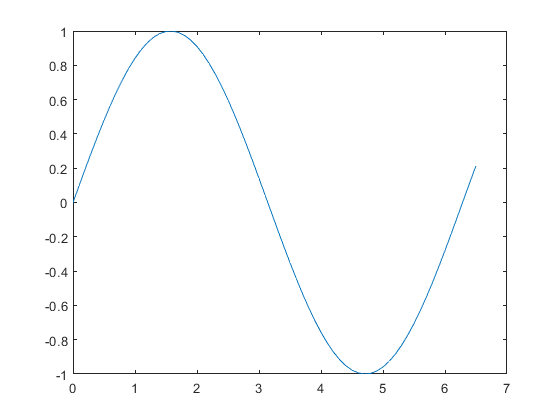

plot(t,sigx); 

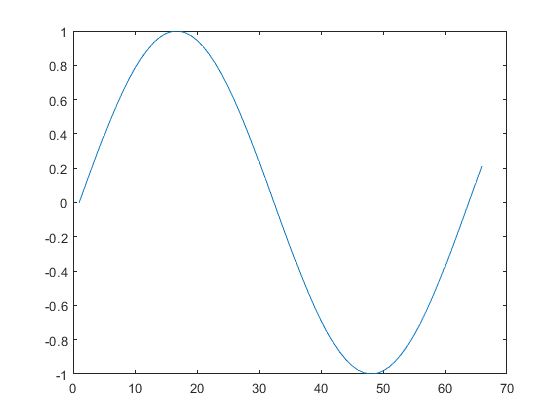

plot(sigx); 

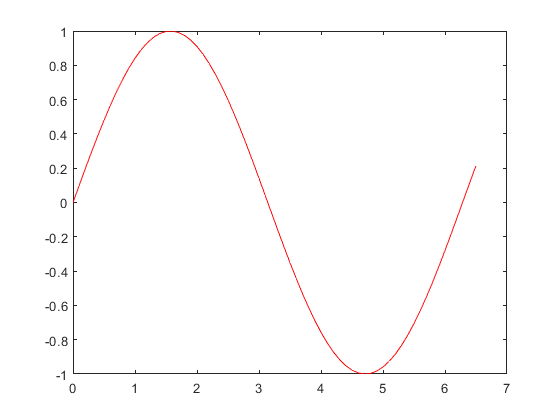

plot(t, sigx, '-r'); 

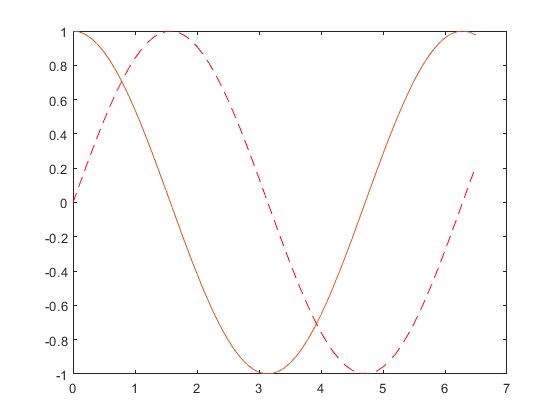

plot(t,sigx,'--r',t,sigy); 

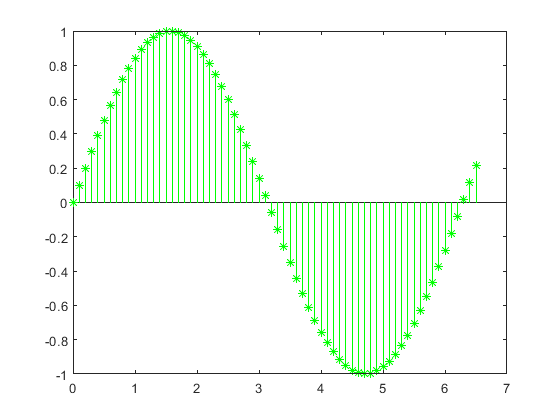

stem(t,sigx,'* g')  %针状图，默认空心圆圈

## Fplot

syms x   %定义符号变量
y = sin(2*pi*x)

$$y = \sin\left(2\,\pi \,x\right)$$

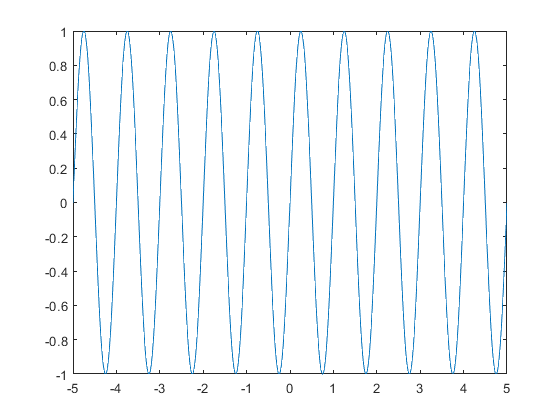

fplot(x,y); %绘制表达式或函数,符号型fplot

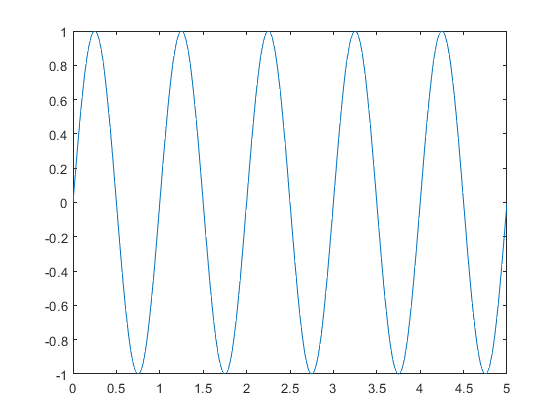

fplot(y, [0 5]);

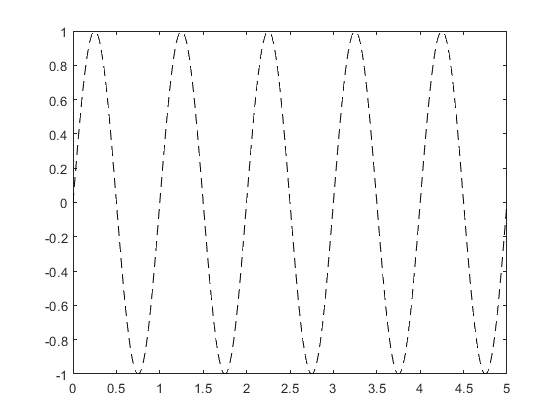

fplot(x,y,[0 5],"Color",'k',"LineStyle","--")  %虚线

%help fplot


## Subplot %一张大图中包含多个小图

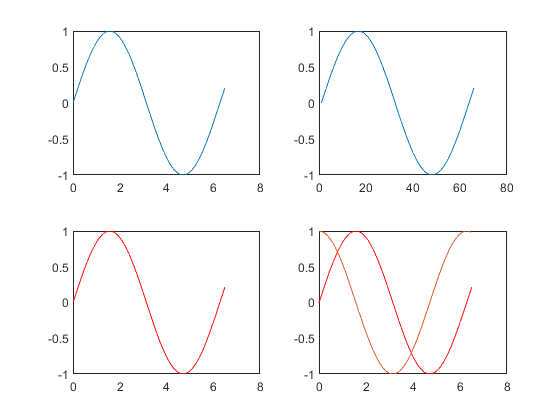

clf;
subplot(2,2,1); plot(t,sigx);
subplot(2,2,2); plot(sigx);
subplot(2,2,3); plot(t,sigx,'-r');
subplot(2,2,4); plot(t,sigx,'-r',t,sigy);

subplot

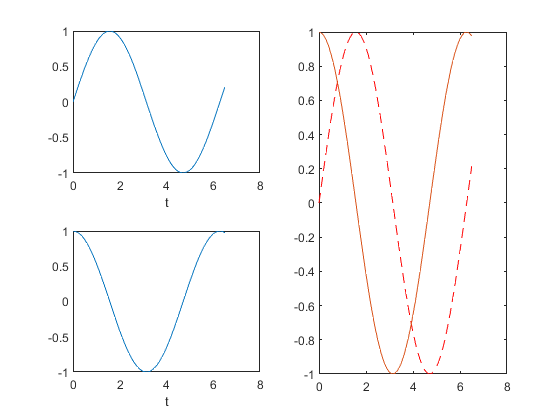

clf;
subplot(2,2,1); plot(t,sigx);xlabel('t');
subplot(2,2,3); plot(t,sigy);xlabel('t');
subplot(2,2,[2 4]); plot(t,sigx,'--r',t,sigy);

## Label

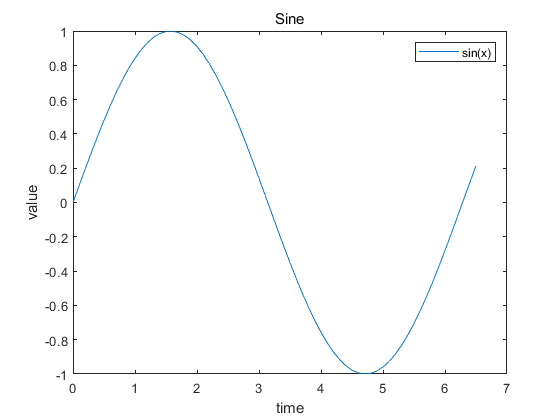

clf;
plot(t,sigx);
title('Sine');
xlabel('time');
ylabel('value');
legend('sin(x)')

## Range  

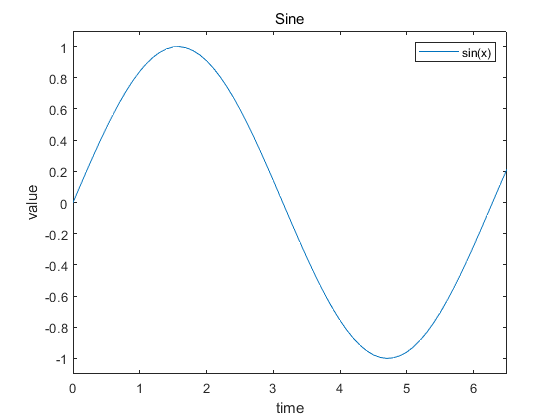

axis([0 6.5 -1.1 1.1]);

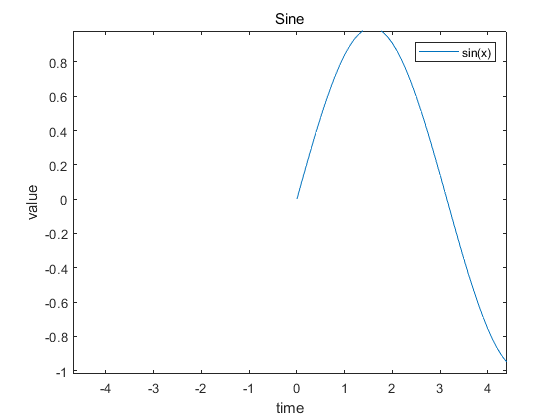

axis([-5 5 -1.1 1.1]);

## Grid

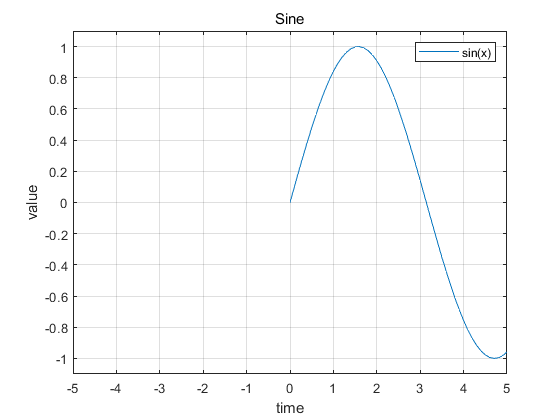

grid on;

# Functions to Generate Elementary Signal（数值法及符号法创建信号）

Both methods is ok：sin、cos、sinc、exp、heaviside、diract（两种方法均可的函数）

### sin(t)、cos(t)    

###  (三角函数，多用途)

t：time axis（时间轴）

Radian frequency and radian is used for **cos** and** sin**.

（Matlab中三角函数使用的是角频率和弧度值，不是频率和角度值）

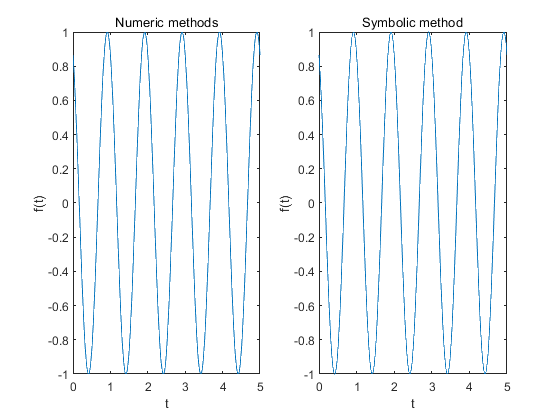

clear; clf;
A = 1;
w = 2*pi;
phi = pi/6;

%Numeric methods 数值法
t = 0:0.01:10;
fn = A*cos(w*t+phi);
subplot(1,2,1); plot(t,fn); axis([0 5 -1 1]); 
xlabel("t");ylabel("f(t)");title('Numeric methods');

% Symbolic methods 符号法
syms ts
fs = A*cos(w*ts+phi);
subplot(1,2,2); fplot(fs); axis([0 5 -1 1]); 
xlabel("t");ylabel("f(t)");title('Symbolic method');

### Sampling：sinc(t)   

### （采样信号，lab5抽样及重建）

t：time axis（时间轴）

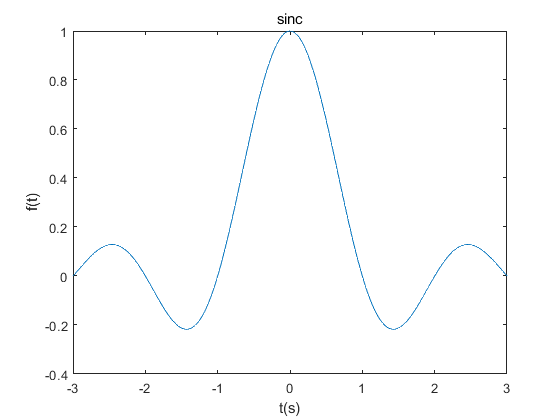

clear; clf;
t = -3:0.01:3;
ft = sinc(t); %sin(t)/t
plot(t,ft); 
title('sinc'); xlabel('t(s)');ylabel('f(t)'); 

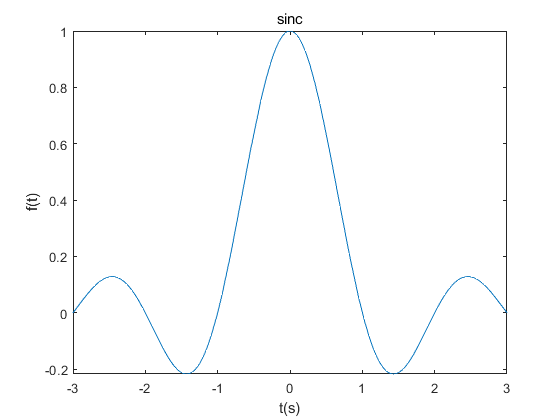


syms x
y =sinc(x);
fplot(y,[-3 3])
title('sinc'); xlabel('t(s)');ylabel('f(t)');

### Exponential：A*exp(a*t)  

### （指数信号，lab3-4傅里叶级数、傅里叶变换）

t：time axis（时间轴）

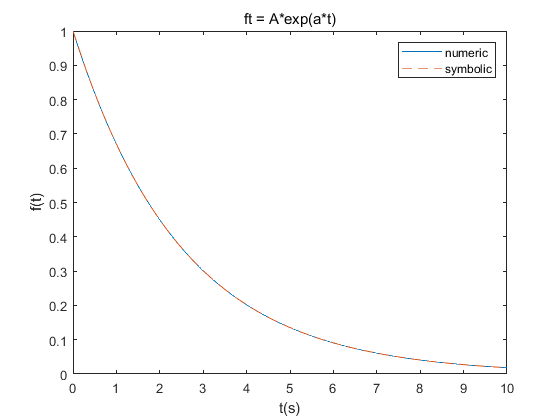

t = 0:0.01:10;
A = 1;  a = -0.4;
ft = A*exp(a*t);
plot(t,ft); hold on;

syms x
y = A*exp(a*x);
fplot(x,y,[0 10],'--'); hold off;
title('ft = A*exp(a*t)'); xlabel('t(s)');ylabel('f(t)');legend("numeric","symbolic");

### **Aperiodic Triangle**： tripuls(t,w,s) 

### （ 三角（形）信号，lab2信号时域分析，lab4傅里叶变换）

t：time axis（时间轴）

w：The width of the base of the triangle, centered at 0.（三角形的底边宽度，以0为中心）

s：Vertex position, range: [-1 1]. （三角形偏斜，  范围： [-1 1]）

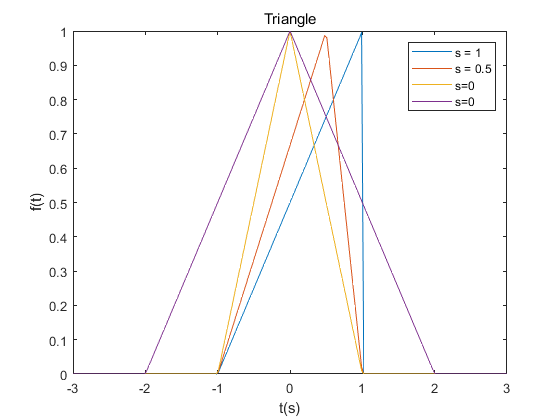

clear; clf;
t = -3:0.03:3;
ft1 = tripuls(t,2,1);
ft2 = tripuls(t,2,0.5);
ft3 = tripuls(t,2,0);
ft4 = tripuls(t,4);   %默认情况下是三角形脉冲信号
plot(t,ft1,t,ft2,t,ft3,t,ft4); 
title('Triangle'); xlabel('t(s)');ylabel('f(t)');
legend('s = 1','s = 0.5','s=0','s=0')

### **Sawtooth or triangle wave**：sawtooth(t,xmax)   

### （锯齿波，lab2信号时域分析，lab3傅里叶级数）

t：time axis（时间轴）

xmax：Vertex position, range: [0 1], periodic: 2pi（ 顶点位置， 范围：[0 1]，周期：2pi）

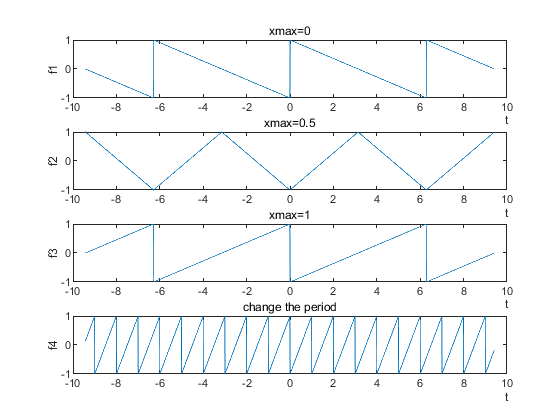

clear; clf;
t = -3*pi:0.01:3*pi;
ft1 = sawtooth(t,0);  %周期为2pi
ft2 = sawtooth(t,0.5);  %该函数在间隔0到2π×width范围内从-1增加到1，然后在间隔2π×width到2π的范围内从1线性减少到-1。
ft3 = sawtooth(t,1);
subplot(4,1,1); plot(t,ft1); title('xmax=0'); xlabel('t','position',[10 -1.5 0]);ylabel('f1');
subplot(4,1,2); plot(t,ft2); title('xmax=0.5'); xlabel('t','position',[10 -1.5 0]);ylabel('f2');
subplot(4,1,3); plot(t,ft3); title('xmax=1'); xlabel('t','position',[10 -1.5 0]);ylabel('f3');

ft4 = sawtooth(2*pi*t,1);
subplot(4,1,4); plot(t,ft4); title('change the period'); xlabel('t','position',[10 -1.5 0]);ylabel('f4');

### **Aperiodic Rectangle**：rectpuls(t,w)  

### （矩形（窗）信号， lab5采样与重建）

t：time axis（时间轴）

w：rectangle width（矩形宽度）

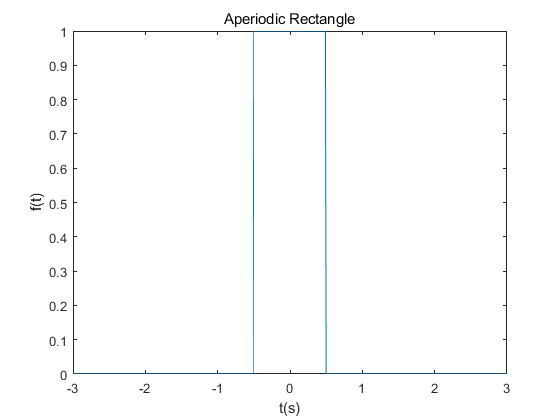

clear; clf;
t = -3:0.01:3;
ft = rectpuls(t,1);
plot(t,ft);
title('Aperiodic Rectangle'); xlabel('t(s)');ylabel('f(t)');

### **Square Wave**：square(t,d)  

### （方波信号，lab2信号时域分析，lab3傅里叶级数）

t：time axis（时间轴）

d：Duty cycle, the proportion of the positive part of the signal, range: [0 100]（占空比，信号为正的部分所占比例，范围：[0 100]）

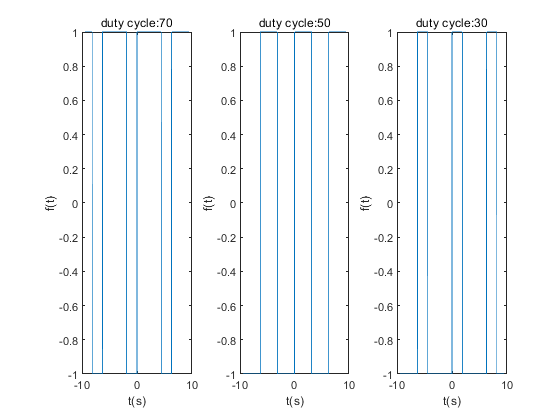

t = -3*pi:0.01:3*pi;
ft = square(t,70);
subplot(1,3,1); plot(t,ft); title('duty cycle:70'); xlabel('t(s)');ylabel('f(t)');
ft = square(t,50);
subplot(1,3,2); plot(t,ft); title('duty cycle:50'); xlabel('t(s)');ylabel('f(t)');
ft = square(t,30);
subplot(1,3,3); plot(t,ft); title('duty cycle:30'); xlabel('t(s)');ylabel('f(t)');

### **Step Function**：heaviside(t)  

### （阶跃信号，很多地方）

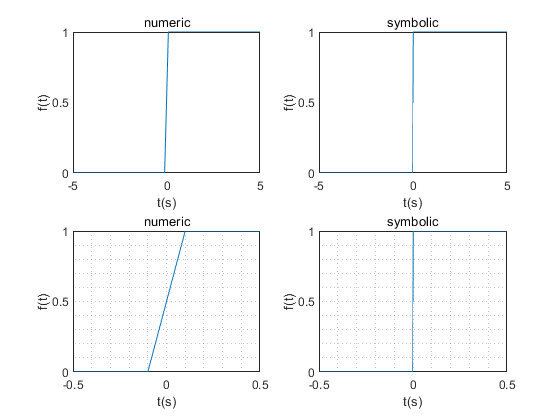

clear;clf;
t = -5:0.1:5;
ft = heaviside(t);  %数值法是以0.1为步进的,阶跃函数在0处的取值为0.5

syms x
y = heaviside(x);

subplot(2,2,1); plot(t,ft); title('numeric');xlabel('t(s)');ylabel('f(t)');
subplot(2,2,2); fplot(x,y); title('symbolic');xlabel('t(s)');ylabel('f(t)');
subplot(2,2,3); plot(t,ft); axis([-0.5 0.5 -inf inf]); title('numeric');xlabel('t(s)');ylabel('f(t)'); grid minor;
subplot(2,2,4); fplot(x,y,[-0.5 0.5]); title('symbolic');xlabel('t(s)');ylabel('f(t)');grid minor;

## **Delta Function: **dirac(x) 

## （重要函数）冲击信号

Use function **sign** to make the impulse signal visiable.

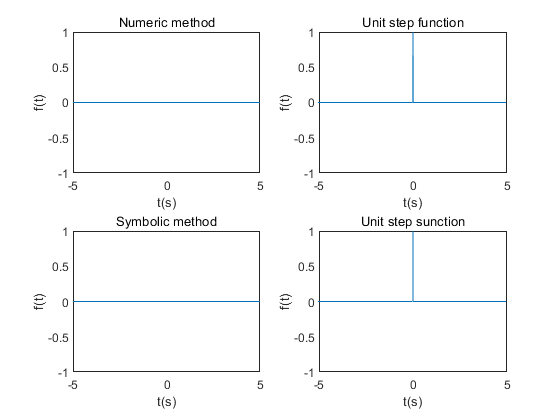

clear; clf;
% Numeric method
t = -5:0.01:5;
fn = dirac(t);   %用sign可视化
subplot(2,2,1); plot(t,fn); title('Numeric method');xlabel('t(s)');ylabel('f(t)');
subplot(2,2,2); plot(t,sign(fn)); axis([-5 5 -1 1]); title('Unit step function');xlabel('t(s)');ylabel('f(t)');

% Symbolic method
syms ts
fs = dirac(ts);
subplot(2,2,3); fplot(fs); title('Symbolic method');xlabel('t(s)');ylabel('f(t)');
subplot(2,2,4); fplot(sign(fs)); title('Unit step sunction');xlabel('t(s)');ylabel('f(t)');

# Signal Operation（信号运算）

## Dot Operation

The difference between the operation with and without dot.

clear; clf;
b = 2*ones(1,5)     

b =      2     2     2     2     2


c = 3*ones(1,5)     % 1*5 matrix

c =      3     3     3     3     3


b'*c

ans =      6     6     6     6     6
     6     6     6     6     6
     6     6     6     6     6
     6     6     6     6     6
     6     6     6     6     6


b.*c %按照元素对应相乘，点乘

ans =      6     6     6     6     6


## Differentiation and Integration

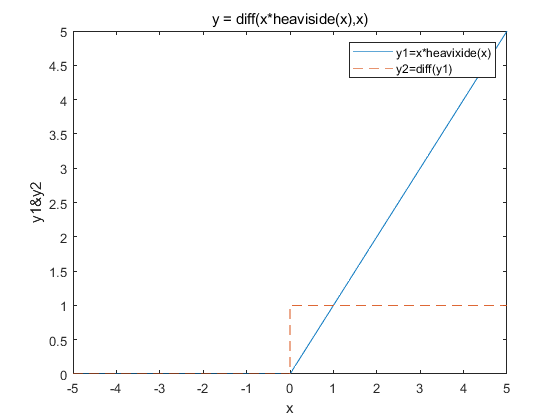

clear; clf;
% symbolic method
syms x
y1 = x*heaviside(x);%阶跃信号
y2 =  diff(y1,x);  %求差值，求导
fplot(y1);hold on;
fplot(y2,'--'); hold off; 
legend("y1=x*heavixide(x)","y2=diff(y1)")
xlabel("x"); ylabel('y1&y2');title('y = diff(x*heaviside(x),x)')

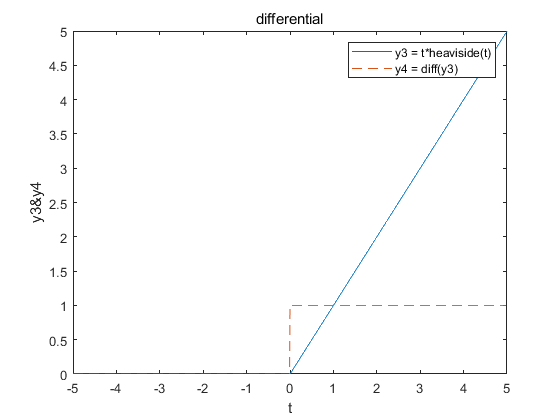

% numeric 2
dt = 0.01;
t = -5:dt:5;
f3 = t.*heaviside(t);
f4 = diff(f3)/dt;       % diff本质是求差值的过程，除dt是为了消除步进的影响，算出导数
plot(t,f3); hold on;
plot(t(1:end-1),f4,'--'); hold off;
legend('y3 = t*heaviside(t)','y4 = diff(y3)');
xlabel('t');ylabel('y3&y4');title('differential')

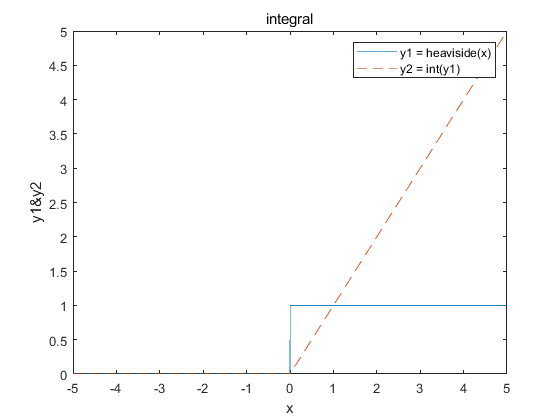

clear; clf;
syms x
y1 = heaviside(x);
y2 = int(y1,x);  %积分
fplot(y1);hold on;
fplot(y2,'--');hold off;
legend('y1 = heaviside(x)','y2 = int(y1)');
xlabel('x');ylabel('y1&y2');title('integral')

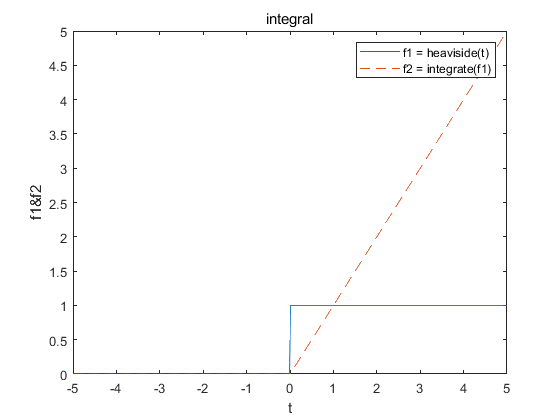

% numeric method
dt = 0.01;
t = -5:dt:5;
f1 = heaviside(t);
f2 = cumtrapz(t, f1); %基于梯形法则的数值积分公式
plot(t,f1,t,f2,'--');
legend('f1 = heaviside(t)','f2 = integrate(f1)');
xlabel('t');ylabel('f1&f2');title('integral')

# Programing Structure

## Loop

% for loop for循环
a = zeros(1,10);
for i=1:10
    a(i)=i;
end
% while  while循环
i = 10;
b = zeros(1,10);
while i > 0
    b(10-i+1) = i;
    i = i-1;
end

## Branch

% if-else-end   用if画了一个阶跃信号
t = -5:0.01:5;
f = zeros(1,length(t));
for i=1:length(t)
    if t(i) < 0
        f(i) = 0;
    elseif t(i) == 0
        f(i) = 0.5;
    else
        f(i) = 1;
    end
end
clf
plot(t, f);


% switch 变量的多分支选择问题，判断
shape = 'triangular';
t = -5:0.01:5;
switch shape
    case 'sine'
        f = sin(t);
    case 'cosine'
        f = cos(t);
    case 'triangular'
        f = tripuls(t,2,0.5);
    otherwise
        f = t;
end
plot(t,f)